# Regular Method

## 2D

% Load 2D mesh
mesh = load_mesh('circle2000_86_stnd');

plotmesh_fiducials(mesh), axis off;

% Check if the file exists
if exist('var/jacobian/2D.mat') == 2
    % File exists, so you can skip running the code or add code here
    disp('File found. Skipping jacobian calculation');
else
    % File doesn't exist, so you can run your code here
    disp('File not found. Calculating jacobian...');

    % Calculate Jacobian at 0 MHz, i.e. CW case
    % This is only for Amplitude data and mua only
    J = jacobian_FD(mesh,0);
    
    % Keep only complete part!
    J = rmfield(J,'complex');
    
    save var/jacobian/2D J -V7.3
        
end

%% Mesh Blob
%% Model activation 5 mm radius in gray matter only
activation_centre_1 = [20 20];

activation_centre_2 = [0, -20];

activation_centre_3 = [-25, 20];

blob_indx_1 = find(sqrt(sum((mesh.nodes-activation_centre_1).^2,2))<=5);

blob_indx_2 = find(sqrt(sum((mesh.nodes-activation_centre_2).^2,2))<=5);

blob_indx_3 = find(sqrt(sum((mesh.nodes-activation_centre_3).^2,2))<=5);

blob_indx = union(blob_indx_1, union(blob_indx_2, blob_indx_3));

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 3;

plotimage(mesh_blob,mesh_blob.region);

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

tic
rhs = J.complete*delta_mua;

%% reconstruct from simulated data
Hess = J.complete*J.complete';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon = J.complete'*inv(Hess+reg)*rhs;
toc

plotimage(mesh,mua_recon);
mua_recon_sq = mua_recon .^ 2;
plotimage(mesh,mua_recon_sq);

## 3D

% Load 3D mesh
load meshes/subject10_stnd.mat

% plot 3D mesh
figure, plotmesh_fiducials(mesh), axis off;

% Check if the file exists
if exist('Jacobian/subject10_stnd_J.mat') == 2
    % File exists, so you can skip running the code or add code here
    disp('File found. Skipping jacobian calculation');

    load Jacobian/subject10_stnd_J.mat
else
    % File doesn't exist, so you can run your code here
    disp('File not found. Calculating jacobian...');

    % Calculate source/detector separation
    SDS = sqrt(sum((mesh.source.coord(mesh.link(:,1),:)-mesh.meas.coord(mesh.link(:,2),:)).^2,2));
    
    % use only channel (source/detector separations) distance of <35 mm
    indx = find(SDS<=35);
    mesh.link = mesh.link(indx,:);
    
    % Calculate Jacobian at 0 MHz, i.e. CW case
    % This is only for Amplitude data and mua only
    J = jacobian_FD(mesh,0);
    
    % Keep only complete part!
    J = rmfield(J,'complex');
    
    save var/jacobian/brain J -V7.3
        
end

File found. Skipping jacobian calculation


%% Mesh Blob
%% Model activation 10 mm radius in gray matter only
activation_centre = [103 132 157];

blob_indx = find(sqrt(sum((mesh.nodes-activation_centre).^2,2))<=20);
gray_indx = find(mesh.region==4);
blob_indx = intersect(blob_indx,gray_indx);

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 20;

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

%% Blob Visualisation
% Slice any axis for a cross-sectional view (x,y,z)
[xgrid,ygrid,zgrid] = meshgrid(47:0.1:182, 132, 68:0.1:190); % 0.1 is the axis resolution
delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),mesh_blob.region,xgrid(:),ygrid(:),zgrid(:));
delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
set(groot, 'DefaultSurfaceEdgeColor', 'none')
figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off;

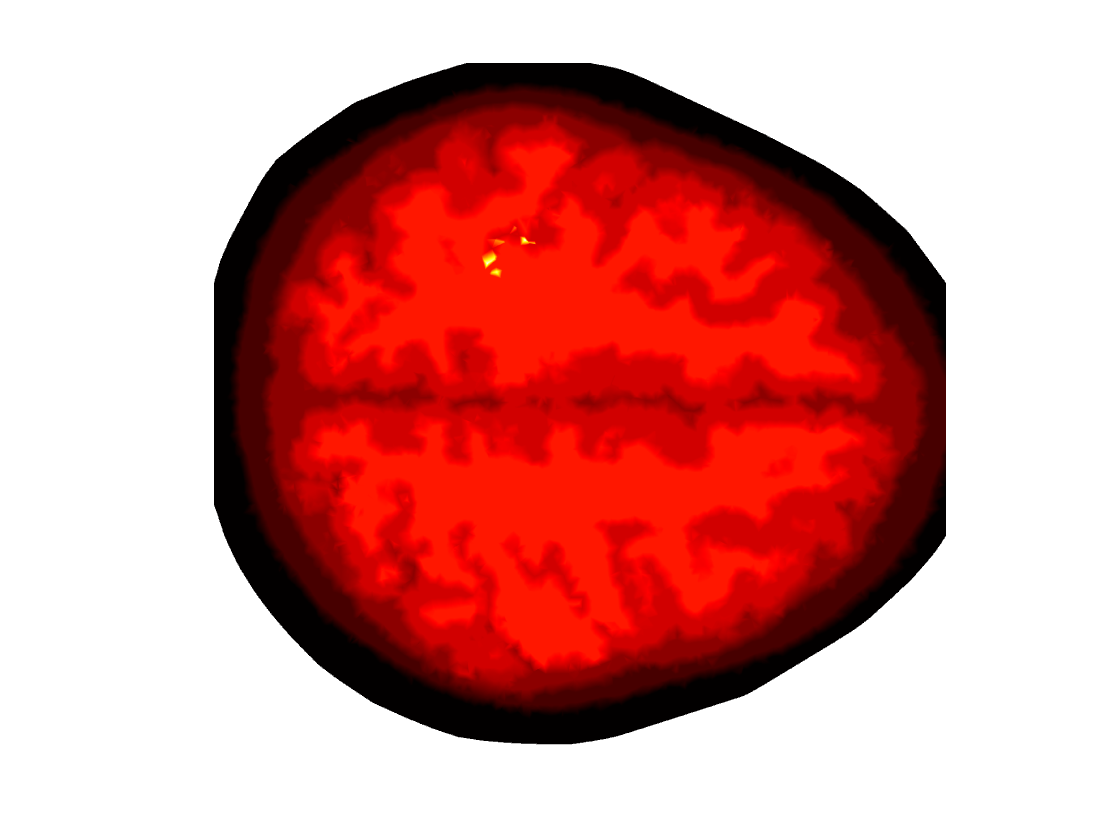

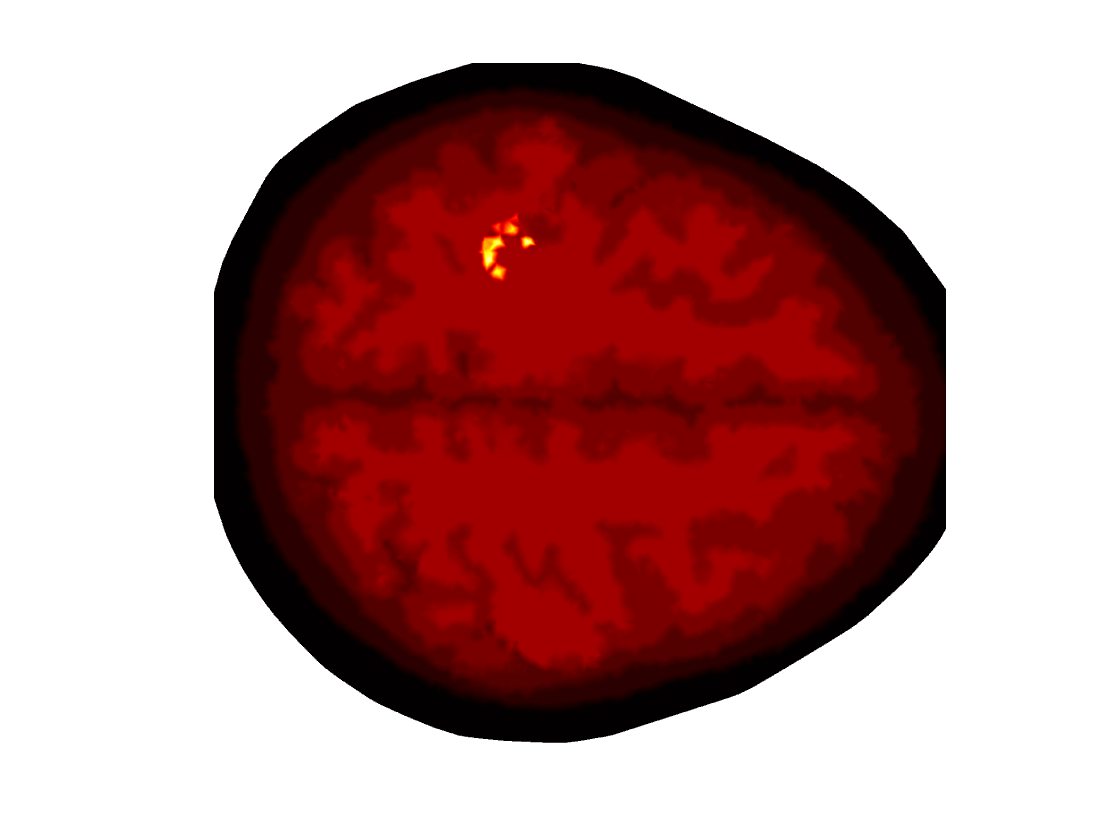

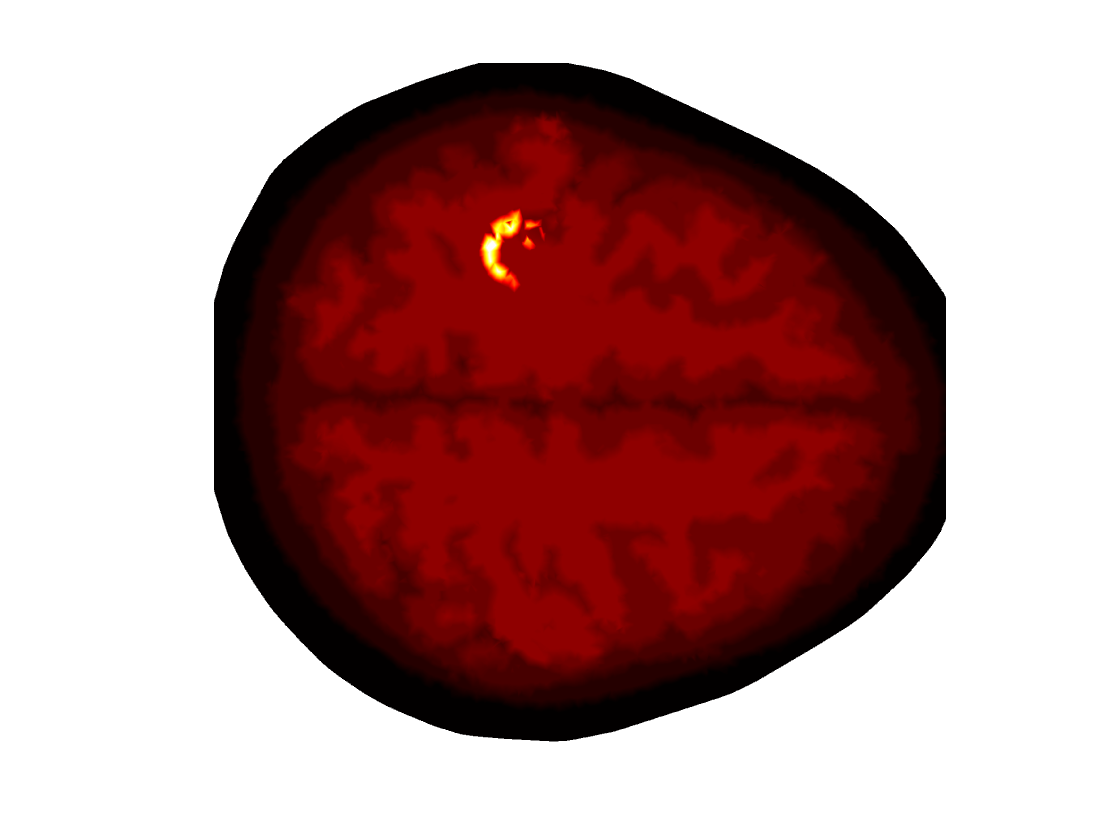

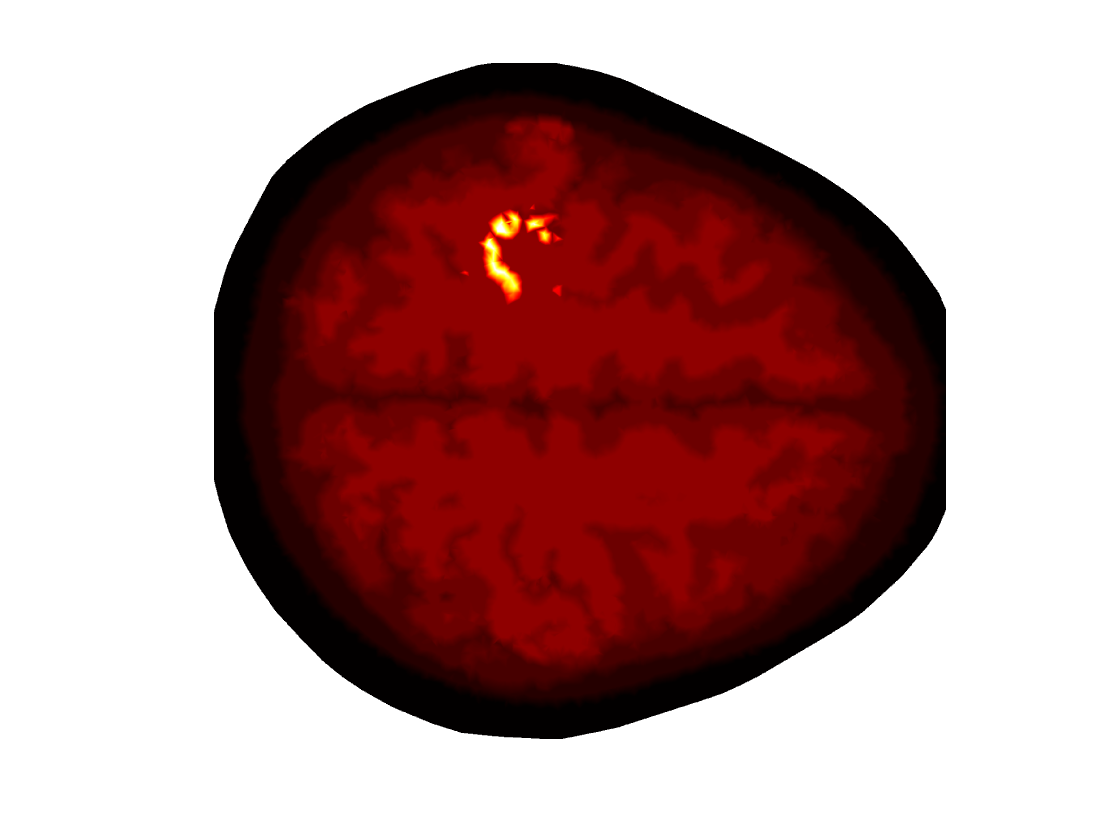

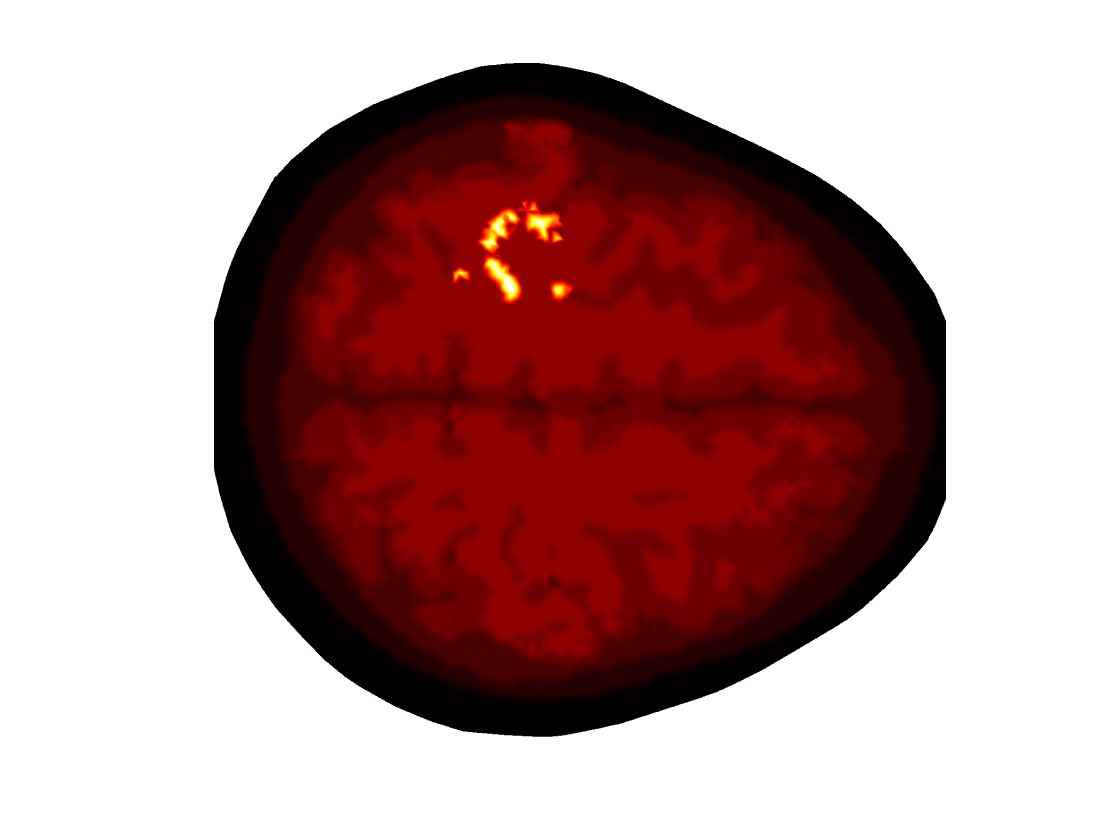

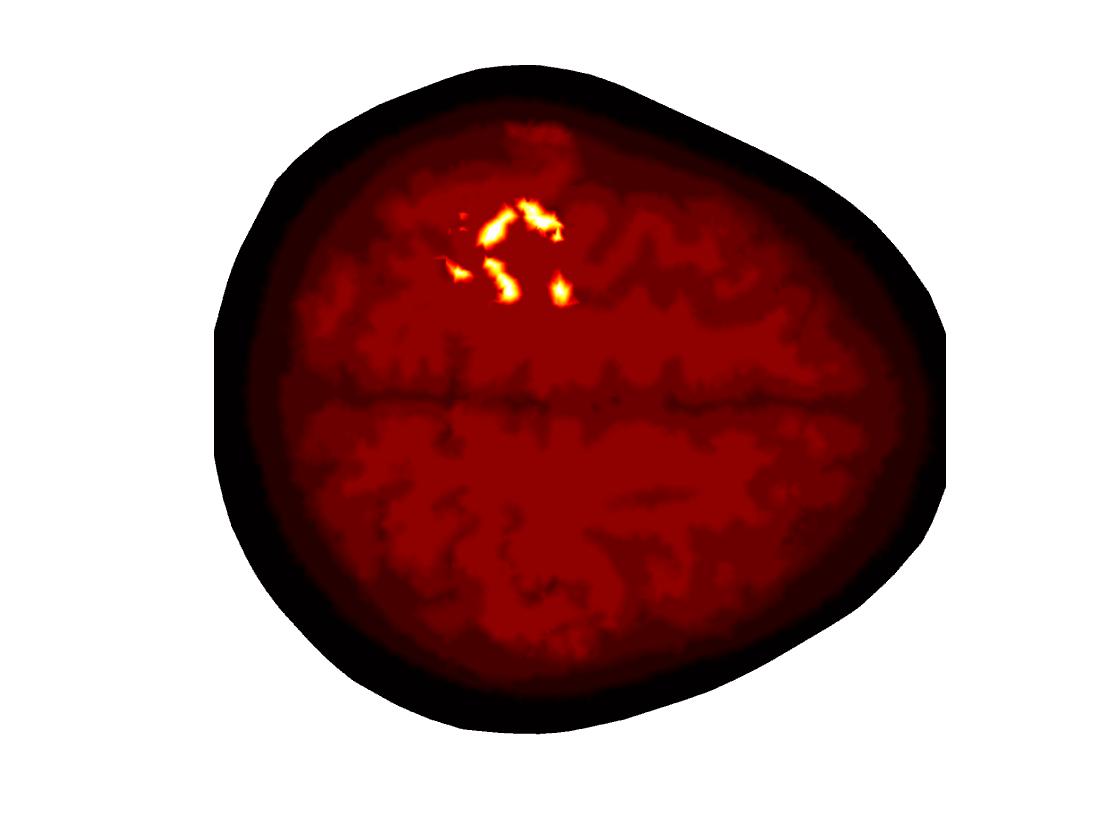

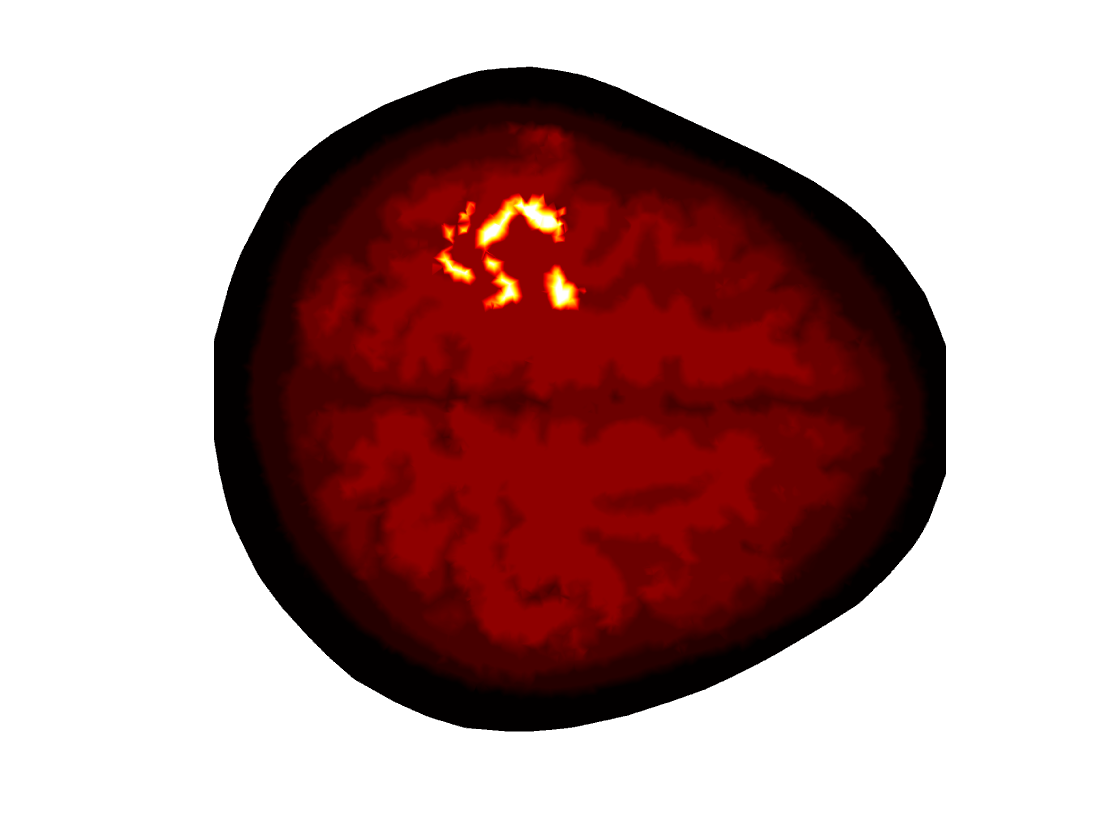

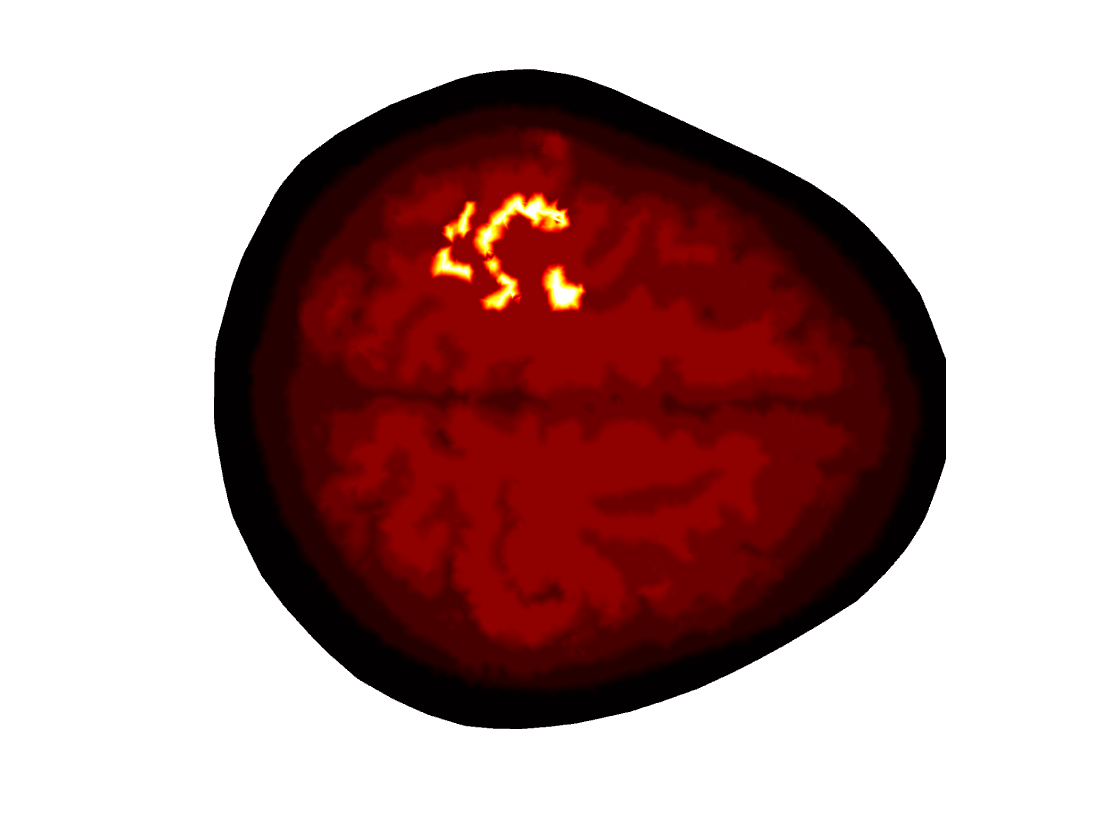

for y = 112:121
    [xgrid,ygrid,zgrid] = meshgrid(40:0.1:195, y, 55:0.1:200);
    delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),mesh_blob.region,xgrid(:),ygrid(:),zgrid(:));
    delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
    set(groot, 'DefaultSurfaceEdgeColor', 'none')
    figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off;
    saveas(gcf,[num2str(y) '.png']);
end 

for z = 147:167
    [xgrid,ygrid,zgrid] = meshgrid(26:0.05:216, 1:0.05:151, z);
    delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),mesh_blob.region,xgrid(:),ygrid(:),zgrid(:));
    delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
    set(groot, 'DefaultSurfaceEdgeColor', 'none')
    figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off, camroll(90);
    saveas(gcf,[num2str(z) '.png']);
end 

% Thresholding
row_sum = sum(J.complete, 1);
tic
threshold_percent = 1; % sensitivity threshold
max_value = max(abs (row_sum));
threshold = max_value * threshold_percent / 100;
selected_indices = find(abs (row_sum) >= threshold);
J1 = J.complete(:, selected_indices);
delta_mua1 = delta_mua(selected_indices);

rhs = J1*delta_mua1;

%% reconstruct from simulated datasa
Hess = J1*J1';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon = J1'*inv(Hess+reg)*rhs;

% Create a zero vector of the same size as the original 'delta_mua'
reconstructed_delta_mua = zeros(1, length(delta_mua));

% Place the selected values at their respective indices
reconstructed_delta_mua(selected_indices) = mua_recon;

% Mua Recon Viz
[xgrid,ygrid,zgrid] = meshgrid(26:0.05:216, 1:0.05:151, 157);
delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),reconstructed_delta_mua,xgrid(:),ygrid(:),zgrid(:));
delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
set(groot, 'DefaultSurfaceEdgeColor', 'none')
figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off, camroll(90);

[xgrid,ygrid,zgrid] = meshgrid(47:0.1:182, 132, 68:0.1:190);
delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),reconstructed_delta_mua,xgrid(:),ygrid(:),zgrid(:));
delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
set(groot, 'DefaultSurfaceEdgeColor', 'none')
figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off;